## 绘制Hata路径损失模型

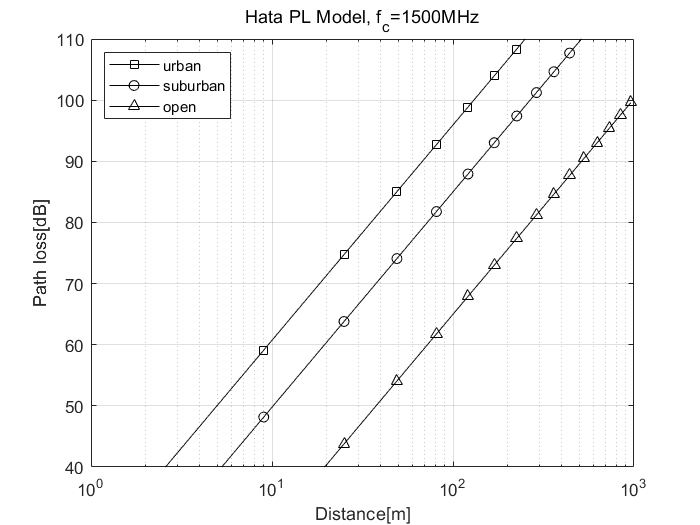

clear,clf
fc = 1.5e9;
htx = 30;
hrx = 2;
distance = (1:2:31).^2;
y_urban = PL_Hata(fc,distance,htx,hrx,'urban');
y_suburban = PL_Hata(fc,distance,htx,hrx,'suburban');
y_open = PL_Hata(fc,distance,htx,hrx,'open');
semilogx(distance,y_urban,'k-s',distance,y_suburban,'k-o',distance,y_open,'k-^')
grid on,axis([1 1000 40 110])
title(['Hata PL Model, f_c=',num2str(fc/1e6),'MHz'])
xlabel('Distance[m]'),ylabel('Path loss[dB]')
legend('urban','suburban','open','Location','northwest')